%{
ES115 - Class-Project Module: RC Circuit Transient Response
Author: Matthew Chietro
Version: 1.0
Date: 2026-04-26

Purpose:
    - To model the transient voltage response of an RC circuit.
    - To simulate capacitor charging and discharging behavior.
    - To analyze how resistance and capacitance affect circuit response.
    - To demonstrate filtering behavior with dynamic input signals.

Input:
    - Time span from 0 to 0.02 seconds
    - Resistance R = 1e3 ohms (varied in sensitivity analysis)
    - Capacitance C = 1e-6 farads
    - Input voltage Vin = 5V (constant, square wave, and noisy signals)
    - Time step values for Euler method comparison

Output:
    - Voltage vs time plots for charging and discharging
    - Comparison of numerical (ode45) and analytical solutions
    - Response to square wave and noisy inputs
    - Error vs timestep plot for Euler method
    - Parameter sensitivity plots (effect of resistance)

Engineering Algorithms:
    - Define differential equation: dVc/dt = (1/RC)*(Vin - Vc)
    - Solve using ode45 (adaptive numerical solver)
    - Implement analytical solution for validation
    - Apply Euler method for step-by-step numerical approximation
    - Loop through different resistance values for sensitivity analysis
    - Simulate dynamic inputs (square wave and noise)
    - Plot and compare results with proper labeling

MATLAB tools/functions:
    - ode45 (ODE solver)
    - exp()
    - plot, xlabel, ylabel, title, legend, grid
    - for-loops
    - anonymous functions (@)
    - loglog
    - square()
    - randn()
    - exportgraphics
    - figure
%}



%% RC Circuit Transient Response 

clear; clc; close all;   % Clear workspace, command window, and close figures



% Basic Parameters

R = 1e3;        % Resistance in ohms (1kΩ)
C = 1e-6;       % Capacitance in farads (1 microfarad)
Vin = 5;        % Input voltage (Volts)

tau = R*C;      % Time constant (how fast circuit responds)
                % Bigger tau = slower response

tspan = [0 0.02];   % Time range for simulation (0 to 0.02 seconds)


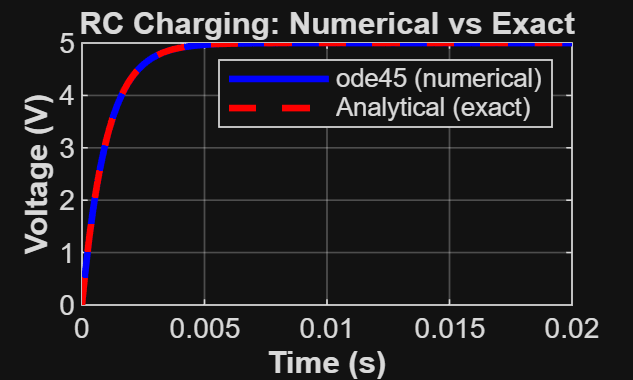


% 1. Charging using ode45 solver

% ode45 is a solver that automatically picks good step sizes
% It solves differential equations more accurately than simple methods

% Define the differential equation:
% dVc/dt = (1/RC)*(Vin - Vc)
f_charge = @(t, Vc) (1/(R*C)) * (Vin - Vc);

% Solve the equation starting from Vc = 0 (uncharged capacitor)
[t1, Vc1] = ode45(f_charge, tspan, 0);

%% ANALYTICAL (EXACT) SOLUTION
% This is the known math formula for comparison
t_exact = linspace(0, 0.02, 1000);
Vc_exact = Vin * (1 - exp(-t_exact/tau));

% Plot both results to compare
figure;
plot(t1, Vc1, 'b', 'LineWidth', 2); hold on;
plot(t_exact, Vc_exact, 'r--', 'LineWidth', 2);

xlabel('Time (s)', 'FontWeight', 'bold');
ylabel('Voltage (V)', 'FontWeight', 'bold');
title('RC Charging: Numerical vs Exact');
legend('ode45 (numerical)','Analytical (exact)');
grid on; box on;

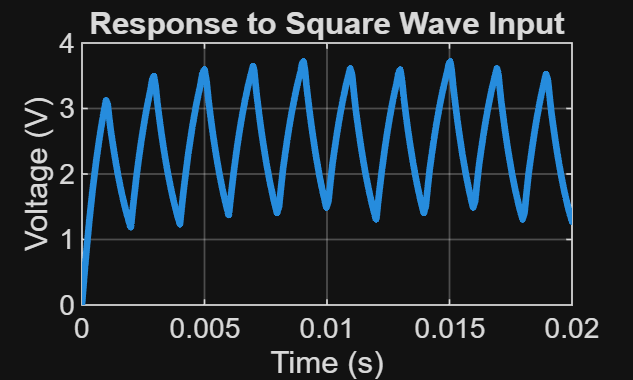


% 2. Square Wave Input (Realistic Signal)
% Instead of constant voltage, we use a signal that switches on/off
% square() creates a signal moving between -1 and 1
% We shift it to go between 0 and 5 volts

f_square = @(t, Vc) (1/(R*C)) * (2.5*square(2*pi*500*t) + 2.5 - Vc);

% Solve again
[t2, Vc2] = ode45(f_square, tspan, 0);

figure;
plot(t2, Vc2, 'LineWidth', 2);

xlabel('Time (s)');
ylabel('Voltage (V)');
title('Response to Square Wave Input');



grid on;

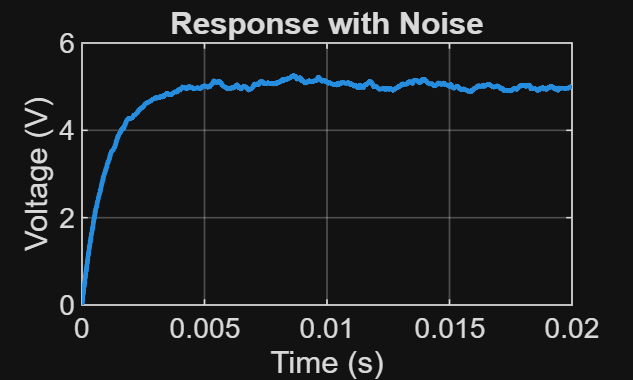


% Noisy Input Signal

% Add randomness (noise) to the voltage
% randn gives random values (simulating real world noise)

Vin_noise = @(t) 5 + 0.5*randn;

f_noise = @(t, Vc) (1/(R*C)) * (Vin_noise(t) - Vc);

[t3, Vc3] = ode45(f_noise, tspan, 0);

figure;
plot(t3, Vc3, 'LineWidth', 1.5);

xlabel('Time (s)');
ylabel('Voltage (V)');
title('Response with Noise');


% Capacitor smooths noise → behaves like a low-pass filter

grid on;

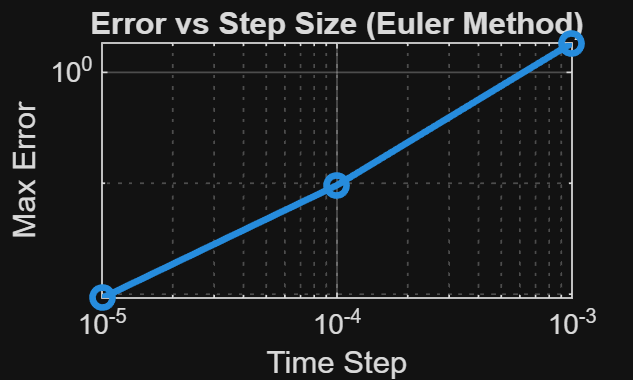



% Euler method (Simple Numerical Method)

% Euler method updates voltage step-by-step:
% V(next) = V(current) + (rate of change)*dt
% It is simple but less accurate than ode45

dt_values = [1e-3, 1e-4, 1e-5];   % Different step sizes
errors = zeros(size(dt_values));  % Store errors

for i = 1:length(dt_values)
    dt = dt_values(i);            % Current time step
    t = 0:dt:0.02;                % Time vector
    Vc = zeros(size(t));          % Initialize voltage
    
    % Loop through time steps
    for k = 1:length(t)-1
        dVc = (1/(R*C)) * (Vin - Vc(k));   % Rate of change
        Vc(k+1) = Vc(k) + dt*dVc;          % Update rule
    end
    
    % Exact solution for comparison
    V_exact = Vin*(1 - exp(-t/tau));
    
    % Compute maximum error
    errors(i) = max(abs(Vc - V_exact));
end

figure;
loglog(dt_values, errors, '-o', 'LineWidth', 2);

xlabel('Time Step');
ylabel('Max Error');
title('Error vs Step Size (Euler Method)');

% Smaller step size → more accurate results

grid on;

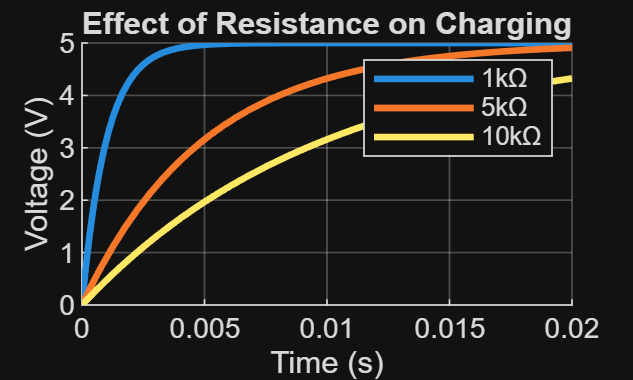

% Parameter Sensitivity (CHANGE R)

% See how changing resistance affects charging speed

R_values = [1e3, 5e3, 10e3];

figure; hold on;

for i = 1:length(R_values)
    R_temp = R_values(i);
    
    % Update equation with new resistance
    f_temp = @(t, Vc) (1/(R_temp*C)) * (Vin - Vc);
    
    [t_temp, Vc_temp] = ode45(f_temp, tspan, 0);
    
    plot(t_temp, Vc_temp, 'LineWidth', 2);
end

xlabel('Time (s)');
ylabel('Voltage (V)');
title('Effect of Resistance on Charging');

legend('1kΩ','5kΩ','10kΩ');

% Higher resistance → slower charging (larger time constant)

grid on;


% Saving the figure

% Save the last plot as a high-quality image
exportgraphics(gcf, 'rc_plot.png', 'Resolution', 300);